%%
% 5281873
clc
close all
clear all

% setup
a = 5; b = 8; c = 3;

NCS.A = [a-b 0.5-c;
         0   1];

NCS.B = [0; 1];

NCS.nx = 2;

NCS.K = [-2 1.6];
% NCS.K = [-2 0];

NCS.h = 0.2;

%% 3.1 

syms hl s

F = expm(NCS.A*NCS.h) - int(expm(NCS.A*s),s,0,NCS.h)*NCS.B*NCS.K

 
F =
 
                   [0.460053340014026    -0.349362814427340]
                   [                                       ]
                   [0.442805516400000    0.867158345040170 ]


NCS_Determinism_loss.F_interval = vpa(F);

NCS_Determinism_loss.F_total_set = [];

for i=1:1:5
    F_extra = expm(NCS.A * (i*NCS.h - NCS.h));
    F_total = F_extra * NCS_Determinism_loss.F_interval;
    NCS_Determinism_loss.F_total_set = [NCS_Determinism_loss.F_total_set; F_total];
end

NCS_Determinism_loss.F_total_set = double(NCS_Determinism_loss.F_total_set)

NCS_Determinism_loss = struct with fields:
     F_interval: [2×2 sym]
    F_total_set: [10×2 double]




for i_upperbound = 1:1:5

    cvx_clear

    cvx_begin sdp

    variable P(2,2) semidefinite

    subject to
            for i = 1:1:i_upperbound
                NCS_Determinism_loss.F_total_set(2*i-1:2*i,:)' * P * NCS_Determinism_loss.F_total_set(2*i-1:2*i,:) - P <= -0.001*eye(NCS.nx);
            end
    cvx_end

    if (cvx_status ~= "Solved")    
        fprintf("maximum delta is:");
        disp(i_upperbound-1)
        break;
    end

end

 
Calling SDPT3 4.0: 6 variables, 3 equality constraints
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  4,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.9e+00|2.0e+01|4.0e+02| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.807|2.6e-06|3.9e+00|7.4e+01| 0.000000e+00  5.401604e-03| 0:0:00| chol  1  1 
 2|1.000|0.990|4.9e-06|4.8e-02|9.0e-01| 0.000000e+00  6.607879e-05| 0:0:00| chol  1  1 
 3|1.000|1.000|1.4e-06|1.0e-03|1.8e-02| 0.000000e+00  1.372567e-06| 0:0:00| chol  1  1 
 4|1.000|1.000|1.1e-07|1.0e-04|1.5e-03| 

maximum delta is:

     3




clear F_total F_extra F i i_upperbound

%% 3.2
NCS_Bernoulli_loss.A0 = double(vpa(expm(NCS.A*NCS.h) - int(expm(NCS.A*s), s, 0, NCS.h)*NCS.B*NCS.K, 4));
NCS_Bernoulli_loss.A1 = double(expm(NCS.A*NCS.h))

NCS_Bernoulli_loss = struct with fields:
    A0: [2×2 double]
    A1: [2×2 double]



p_ub = 1; p_lb=0;
delta = 1; 
iterations = [];

while (delta > 0.0001)

    p_sample = (p_ub+p_lb)/2;
    p = p_sample;

    % LMIs
    cvx_clear
    cvx_begin sdp

        variable P(2,2) semidefinite

        subject to
            P - (1-p)*NCS_Bernoulli_loss.A0' * P * NCS_Bernoulli_loss.A0 - p*NCS_Bernoulli_loss.A1' * P * NCS_Bernoulli_loss.A1 >= 0.0001*eye(NCS.nx);
    
    cvx_end

    if(cvx_status == "Solved")
        temp_iterations=[p_sample,"Solved"];
        iterations=[iterations;temp_iterations];
        p_lb = p_sample;
    else
        temp_iterations=[p_sample,"Infeasible"];
        iterations=[iterations;temp_iterations];
        p_ub = p_sample;
    end
    
    delta = p_ub-p_lb;
end

 
Calling SDPT3 4.0: 6 variables, 3 equality constraints
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  4,   num. of sdp  blk  =  2
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|1.3e+01|2.0e+01|4.0e+02| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.955|0.851|5.9e-01|3.1e+00|4.8e+01| 0.000000e+00  1.060835e-03| 0:0:00| chol  1  1 
 2|1.000|0.902|5.3e-06|3.1e-01|5.3e+00| 0.000000e+00  1.996294e-04| 0:0:00| chol  1  1 
 3|1.000|0.992|3.2e-06|3.5e-03|6.0e-02| 0.000000e+00  2.277987e-06| 0:0:00| chol  1  1 
 4|1.000|1.000|1.0e-06|1.0e-04|1.6e-03| 

NCS_Bernoulli_loss.p_max = p_ub;
fprintf("maximum p is:");

maximum p is:

disp(NCS_Bernoulli_loss.p_max)

    0.5858




clear delta p_lb p_ub p_sample p  



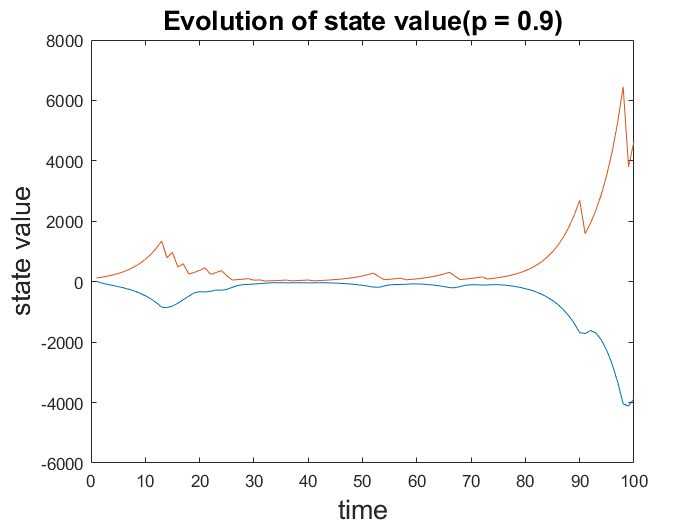

%% 3.3
p_test = 0.58;
p_test = 0.8;
Total_Timestep = 100;
packet_loss_history = zeros(1, Total_Timestep);

x_0 = [100; 100];

x = zeros(NCS.nx,Total_Timestep);

for iTime = 1:1:Total_Timestep
    q = rand(1);
    if (q < p_test)
        % packet loss happen
        packet_loss_history(iTime) = 1;
        if (iTime == 1)
            x(:, iTime) = NCS_Bernoulli_loss.A1*x_0;
        else
            x(:, iTime) = NCS_Bernoulli_loss.A1*x(:,iTime-1);
        end
    else
        % packet have not lost
        packet_loss_history(iTime) = 0;
        if (iTime == 1)
            x(:,iTime) = NCS_Bernoulli_loss.A0*x_0;
        else
            x(:,iTime) = NCS_Bernoulli_loss.A0*x(:,iTime-1);
        end
    end
end


plot(1:1:Total_Timestep, x)
xlabel("time", 'FontSize', 16); 
ylabel("state value", 'FontSize', 16);
title("Evolution of state value(p = 0.9)", 'FontSize', 16)


clear Total_Timestep packet_loss_history x x_0 q iTime p_test
 

%% 3.4
lambda_ub = 1; lambda_lb = 0;

delta = 1;
iterations = [];
L_ub = 100;
while (delta > 0.001)

    lambda_sample = (lambda_ub+lambda_lb)/2;

    lambda = lambda_sample;

    % LMIs
    cvx_clear
    cvx_begin sdp
        variable P(2,2) semidefinite
        subject to
            NCS_Bernoulli_loss.A0' * P * NCS_Bernoulli_loss.A0 - lambda*P <= -0.01*eye(NCS.nx)
            NCS_Bernoulli_loss.A1' * P * NCS_Bernoulli_loss.A1 - L_ub*P <= -0.01*eye(NCS.nx);
    cvx_end

    if(cvx_status=="Solved")
        temp_iterations = [lambda_sample,"Solved"];
        iterations=[iterations;temp_iterations];

        lambda_ub = lambda_sample;
    else
        temp_iterations=[lambda_sample,"Infeasible"];
        iterations=[iterations;temp_iterations];

        lambda_lb = lambda_sample;
    end
    delta = lambda_ub - lambda_lb;
end

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.9e+02|2.0e+02|3.2e+03|-2.990075e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.975|0.925|2.5e+01|1.5e+01|1.0e+02|-2.087254e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.694|0.746|7.7e+00|3.8e+00|3.5e+01|-5.241682e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.562|4.9e-06|1.7e+00|1.6e+01|-1.991331e+00  0.000000e+0


% then use the maximum possible lambda for further checking

lambda_samples = lambda_ub : 0.02 : 0.8;

iterations = []; lambda_pmax=[];

for i_lambda_samples=1:1:length(lambda_samples)

    delta = 1;
   
    lambda_sample = lambda_samples(i_lambda_samples);   
    lambda = lambda_sample;
    L_ub = 1; L_lb = 1;

    while true

        cvx_clear
        cvx_begin sdp
    
            variable P(2,2) semidefinite
    
            subject to
                NCS_Bernoulli_loss.A0' * P * NCS_Bernoulli_loss.A0 - lambda*P <= -0.01*eye(NCS.nx);
                NCS_Bernoulli_loss.A1' * P * NCS_Bernoulli_loss.A1 - L_ub*P <= -0.01*eye(NCS.nx);

        cvx_end

        if (cvx_status ~= "Solved")
            L_ub = L_ub + 10;
        else
            break;
        end  
    end

    while (delta>0.001)

        L = (L_ub+L_lb)/2;

        % LMIs
        cvx_clear
        cvx_begin sdp
    
            variable P(2,2) semidefinite
    
            subject to
                NCS_Bernoulli_loss.A0' * P * NCS_Bernoulli_loss.A0 - lambda*P <= -0.01*eye(NCS.nx);
                NCS_Bernoulli_loss.A1' * P * NCS_Bernoulli_loss.A1 - L*P <= -0.01*eye(NCS.nx);
        
        cvx_end
    
        if(cvx_status == "Solved")
    
            temp_p_max = -log10(lambda)/(log10(L/lambda));
    
            temp_iterations = [L,lambda,1,temp_p_max];
            iterations=[iterations;temp_iterations];
    
            L_ub = L;             
        else
    
            temp_iterations = [L,lambda,0,0];
            iterations = [iterations;temp_iterations];
    
            L_lb = L;
        end
        delta = L_ub-L_lb;
    end



end

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+01|2.4e+01|6.0e+02|-1.505730e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.941|0.905|1.6e+00|2.4e+00|5.0e+01|-2.818712e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.812|1.9e-05|4.5e-01|1.3e+01|-6.403045e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.920|1.9e-06|3.7e-02|5.6e-01|-7.040530e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.4e+01|2.4e+01|6.0e+02|-2.816768e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.846|0.887|8.3e+00|2.8e+00|8.1e+01|-2.100867e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.666|0.852|2.8e+00|4.2e-01|2.9e+01|-2.842286e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.850|0.793|4.1e-01|8.9e-02|5.2e+00|-5.192640e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+01|2.4e+01|6.0e+02|-1.477110e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.936|0.903|1.8e+00|2.4e+00|5.2e+01|-2.788936e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.834|1.8e-05|4.1e-01|1.2e+01|-6.446828e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.913|2.7e-06|3.7e-02|5.4e-01|-7.174153e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.4e+01|2.4e+01|6.0e+02|-2.813258e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.844|0.890|8.4e+00|2.7e+00|8.1e+01|-2.080390e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.661|0.889|2.9e+00|3.1e-01|2.9e+01|-2.712224e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.880|1.000|3.4e-01|1.0e-03|3.2e+00|-2.286655e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.8e+01|2.4e+01|6.0e+02|-1.448489e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.932|0.899|1.9e+00|2.5e+00|5.4e+01|-2.760322e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.865|1.6e-05|3.5e-01|9.8e+00|-6.250792e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.903|5.8e-06|3.5e-02|4.6e-01|-7.096842e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.4e+01|2.4e+01|6.0e+02|-2.809749e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.842|0.893|8.6e+00|2.7e+00|8.1e+01|-2.059945e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.658|0.932|2.9e+00|1.9e-01|2.9e+01|-2.578200e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.939|1.000|1.8e-01|1.0e-03|1.7e+00|-6.868353e-02  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|2.4e+01|6.0e+02|-1.419869e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.929|0.895|2.0e+00|2.6e+00|5.6e+01|-2.732804e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.830|1.5e-05|4.5e-01|1.2e+01|-5.996153e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.928|1.1e-05|3.3e-02|3.9e-01|-6.595525e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.806239e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.839|0.896|8.7e+00|2.6e+00|8.1e+01|-2.039534e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.657|0.983|3.0e+00|5.4e-02|2.9e+01|-2.440477e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.980|1.000|5.9e-02|1.0e-03|5.6e-01|-7.740069e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|2.4e+01|6.0e+02|-1.391249e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.925|0.891|2.2e+00|2.7e+00|5.9e+01|-2.706314e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.789|1.3e-05|5.8e-01|1.5e+01|-5.723057e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.942|1.4e-05|3.4e-02|4.0e-01|-6.160812e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.802730e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.837|0.899|8.9e+00|2.5e+00|8.1e+01|-2.019159e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.659|1.000|3.0e+00|1.0e-02|2.9e+01|-2.299382e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.3e-02|1.0e-03|4.1e-01|-3.338900e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|2.4e+01|6.0e+02|-1.362629e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.923|0.887|2.3e+00|2.8e+00|6.1e+01|-2.680789e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.766|1.2e-05|6.6e-01|1.7e+01|-5.450316e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.948|1.6e-05|3.5e-02|4.0e-01|-5.810423e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.799220e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.835|0.903|9.1e+00|2.4e+00|8.1e+01|-1.998821e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.662|1.000|3.1e+00|1.0e-02|3.0e+01|-2.155305e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.3e-02|1.0e-03|4.2e-01|-3.068612e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.9e+01|2.4e+01|6.0e+02|-1.334008e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.920|0.882|2.3e+00|2.9e+00|6.3e+01|-2.656168e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.753|1.1e-05|7.3e-01|1.8e+01|-5.218799e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.952|1.7e-05|3.6e-02|4.0e-01|-5.532747e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.795711e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.833|0.906|9.2e+00|2.3e+00|8.0e+01|-1.978523e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.668|1.000|3.1e+00|1.0e-02|3.0e+01|-2.008704e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.3e-02|1.0e-03|4.1e-01|-2.825316e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e+01|2.4e+01|6.0e+02|-1.305388e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.918|0.878|2.4e+00|3.0e+00|6.5e+01|-2.632398e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.737|1.0e-05|8.0e-01|1.9e+01|-5.110726e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.955|1.8e-05|3.7e-02|4.1e-01|-5.389003e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.792201e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.831|0.910|9.3e+00|2.3e+00|8.0e+01|-1.958267e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.676|1.000|3.0e+00|1.0e-02|2.9e+01|-1.860107e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.2e-02|1.0e-03|4.1e-01|-2.590235e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e+01|2.4e+01|6.0e+02|-1.276768e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.917|0.874|2.5e+00|3.1e+00|6.7e+01|-2.609431e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.728|9.1e-06|8.5e-01|2.0e+01|-4.995121e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.957|1.8e-05|3.8e-02|4.2e-01|-5.249634e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.5e+01|2.4e+01|6.0e+02|-2.788692e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.829|0.914|9.5e+00|2.2e+00|8.0e+01|-1.938054e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.686|1.000|3.0e+00|1.0e-02|2.9e+01|-1.710121e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.1e-02|1.0e-03|4.0e-01|-2.358502e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.0e+01|2.4e+01|6.0e+02|-1.248148e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.916|0.870|2.6e+00|3.2e+00|6.8e+01|-2.587229e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.725|8.4e-06|8.9e-01|2.0e+01|-4.876821e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.958|1.9e-05|3.8e-02|4.2e-01|-5.114429e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.6e+01|2.4e+01|6.0e+02|-2.785182e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.827|0.917|9.6e+00|2.1e+00|8.0e+01|-1.917885e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.699|1.000|2.9e+00|1.0e-02|2.8e+01|-1.559446e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|4.0e-02|1.0e-03|3.8e-01|-2.129225e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.1e+01|2.4e+01|6.0e+02|-1.219527e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.866|2.6e+00|3.3e+00|7.0e+01|-2.565760e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.725|7.7e-06|9.1e-01|2.0e+01|-4.758910e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.959|1.9e-05|3.8e-02|4.2e-01|-4.983981e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.6e+01|2.4e+01|6.0e+02|-2.781673e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.825|0.921|9.8e+00|2.0e+00|8.0e+01|-1.897765e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.712|1.000|2.8e+00|1.0e-02|2.7e+01|-1.416682e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.986|1.000|3.8e-02|1.0e-03|3.6e-01|-1.915545e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.1e+01|2.4e+01|6.0e+02|-1.190907e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.862|2.6e+00|3.4e+00|7.1e+01|-2.545002e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.728|7.2e-06|9.3e-01|2.0e+01|-4.643226e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.959|1.9e-05|3.9e-02|4.1e-01|-4.858757e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.6e+01|2.4e+01|6.0e+02|-2.778163e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.823|0.925|9.9e+00|1.9e+00|7.9e+01|-1.877693e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.725|1.000|2.7e+00|1.0e-02|2.6e+01|-1.281884e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|3.6e-02|1.0e-03|3.4e-01|-1.716617e-03  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|3.1e+01|2.4e+01|6.0e+02|-1.162287e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.915|0.858|2.7e+00|3.5e+00|7.2e+01|-2.524937e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|1.000|0.733|6.8e-06|9.4e-01|2.0e+01|-4.530756e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|1.000|0.960|1.9e-05|3.9e-02|4.1e-01|-4.738924e-01  0.000000e+0

 
Calling SDPT3 4.0: 9 variables, 3 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints =  3
 dim. of sdp    var  =  6,   num. of sdp  blk  =  3
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.6e+01|2.4e+01|6.0e+02|-2.774654e-01  0.000000e+00| 0:0:00| chol  1  1 
 1|0.821|0.930|1.0e+01|1.8e+00|7.9e+01|-1.857672e-01  0.000000e+00| 0:0:00| chol  1  1 
 2|0.741|1.000|2.6e+00|1.0e-02|2.4e+01|-1.147361e-01  0.000000e+00| 0:0:00| chol  1  1 
 3|0.987|1.000|3.4e-02|1.0e-03|3.2e-01|-1.519989e-03  0.000000e+0

% 
% lambda_pmax

clear i_lambda_samples delta L L_lb L_ub lambda lambda_ub lambda_lb
clear lambda_sample lambda_samples temp_iterations temp_p_max

%% 3.5
p00_samples = 0:0.05:1;
p11_samples = 0:0.05:1;

guaranteed = ones(length(p00_samples),length(p11_samples));

for i = 1:1:length(p00_samples)
    p00 = p00_samples(i);
    
    for j = 1:1:length(p11_samples)
        p11 = p11_samples(j);

        cvx_clear
        cvx_begin sdp

            variable P0(2,2)  semidefinite
            variable P1(2,2)  semidefinite

            subject to
                P0 - (p00 * NCS_Bernoulli_loss.A0' * P0 * NCS_Bernoulli_loss.A0 + (1-p00) * NCS_Bernoulli_loss.A1' * P1 * NCS_Bernoulli_loss.A1) >= 0.001*eye(NCS.nx);
                P1 - (p11 * NCS_Bernoulli_loss.A1' * P1 * NCS_Bernoulli_loss.A1 + (1-p11) * NCS_Bernoulli_loss.A0' * P0 * NCS_Bernoulli_loss.A0) >= 0.001*eye(NCS.nx);

        cvx_end

        if (cvx_status == "Solved")     
            guaranteed(i, j) = 0;
        end
    end
end

 
Calling SDPT3 4.0: 12 variables, 6 equality constraints
------------------------------------------------------------

 num. of constraints =  6
 dim. of sdp    var  =  8,   num. of sdp  blk  =  4
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
   HKM      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|2.0e+01|2.8e+01|8.0e+02| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|0.977|0.805|4.5e-01|5.6e+00|1.3e+02| 0.000000e+00  1.829853e-02| 0:0:00| chol  1  1 
 2|1.000|0.980|4.4e-05|1.2e-01|2.8e+00| 0.000000e+00  3.578666e-04| 0:0:00| chol  1  1 
 3|1.000|0.998|4.5e-06|1.3e-03|2.9e-02| 0.000000e+00  3.698909e-06| 0:0:00| chol  1  1 
 4|1.000|1.000|2.8e-07|1.0e-04|2.0e-03|



contourf(p11_samples, p00_samples, guaranteed)
xlabel("value of p11", 'FontSize', 16);
ylabel("value of p00", 'FontSize', 16);
title("MSS guaranteed area under Gilbert-Elliot models ", 'FontSize', 16)

clear p11 p11_samples p00 p00_samples 